## MMC RMS Current approximation

More information can be found on the Emma Mk1 DRSSTC Gitbook documentation.

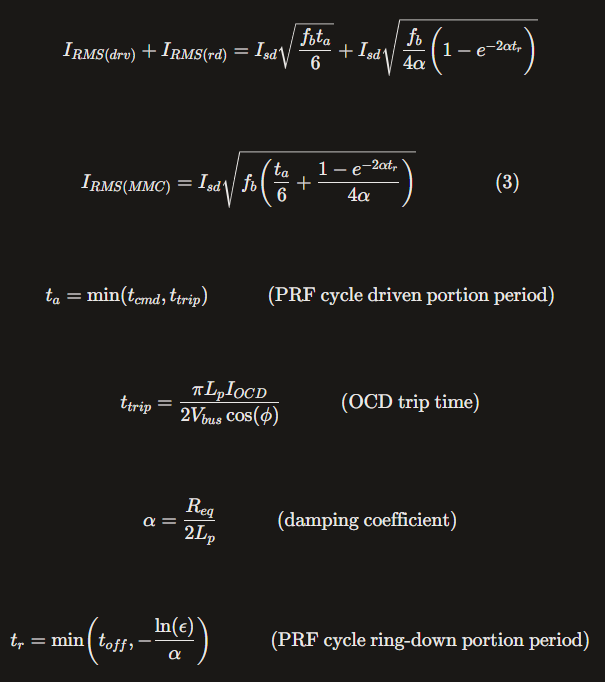

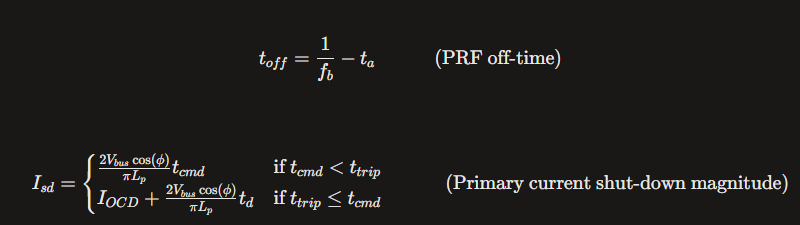

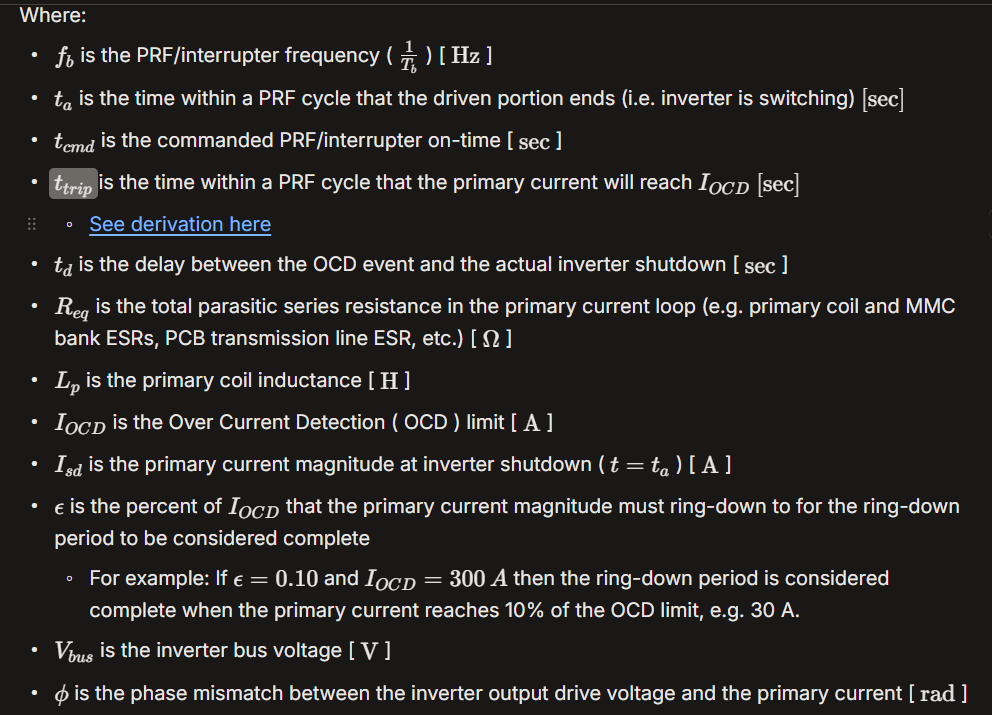

function i_mmc_rms = approx_mmc_rms_current(prf_freq, prf_on_time, ocd_lim, phase_err_rad, R_eq, epsil, drsstc)

fb = prf_freq;

delta = phase_err_rad;
t_cmd = prf_on_time;
t_trip = (pi*drsstc.Lp*ocd_lim)/(2*drsstc.Vbus*cos(delta));

t_a = min(t_cmd, t_trip);

if t_cmd < t_trip
    I_shut = ((2*drsstc.Vbus*cos(delta))/(pi*drsstc.Lp))*t_cmd;
elseif t_trip <= t_cmd
    I_shut = ocd_lim + ((2*drsstc.Vbus*cos(delta))/(pi*drsstc.Lp))*drsstc.t_d;
end

alpha = R_eq/(2*drsstc.Lp);

t_r = min((1/fb)-t_a,(-log(epsil))/alpha);

i_mmc_rms = I_shut*sqrt(fb*( (t_a/6) + (1-exp(-2*alpha*t_r))/(4*alpha) ) );

end